## [LSBoost (XGBoost) Regressor](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor)

The LSBoost is the MATLAB equivalent of Python's XGBoost.

LSBoost is a type of supervised learning algorithm in MATLAB that can be used to make predictions on continuous numerical data. It is an implementation of the least-squares boosting machine learning algorithm, which is a type of ensemble learning method that combines the predictions of multiple weaker models to create a stronger, more accurate model.

LSBoost works by building an ensemble of linear models, where each model is trained to make predictions based on a subset of the available data. The models are grown sequentially, with each model learning from the mistakes of the previous model. The final prediction is made by taking the weighted average of the predictions from all of the models in the ensemble.

One of the key advantages of LSBoost is its ability to handle missing data and large datasets efficiently. It also has a number of hyperparameters that can be tuned to improve model performance, including the learning rate, depth of the trees, and regularization parameters.

Overall, LSBoost is a powerful and widely-used tool for regression tasks in MATLAB, and it has been applied successfully to a variety of real-world problems such as predictive modeling, time series forecasting, and customer churn prediction.

Advantages: Effective with large data sets. LSBoost does not need normalized features and works well if the data is nonlinear, non-monotonic, or with segregated clusters.

Disadvantages: LSBoost can over-fit the data, especially if the models are too complex with noisy data.

% generate regression dataset
X = randn(1000, 10); % 1000 samples, 10 features
w = randn(8, 1); % 8 informative features
y = X(:,1:8)*w + randn(1000,1)*0.5; % response variable

% Split data into testing and training sets
n_samples = length(y);
[trainInd,~,testInd] = dividerand(n_samples,0.8,0,0.2);
X_train = X(trainInd,:);
y_train = y(trainInd);
X_test = X(testInd,:);
y_test = y(testInd);

% train LSBoost model
mdl = fitrensemble(X_train, y_train, 'Method', 'LSBoost');

% make predictions on testing set
y_pred = predict(mdl, X_test);

% evaluate model performance
R2 = 1 - sum((y_test - y_pred).^2)/sum((y_test - mean(y_test)).^2);
fprintf('R2 = %.2f\n', R2);

R2 = 0.69



% get feature importances
imp = predictorImportance(mdl);
t = table((1:10)', imp', 'VariableNames', {'Feature', 'Gain'});
t = sortrows(t, 'Gain', 'descend');
disp(t);

    Feature       Gain   
    _______    __________

       7        0.0037094
       5        0.0015053
       2        0.0013269
       8        0.0011651
       4       0.00056548
       6       0.00027081
       1       0.00021819
       3       0.00012949
       9       8.7946e-05
      10       6.9062e-05




% create table from feature importances
fi = predictorImportance(mdl);
n = (1:10)';
d = table(n, fi', 'VariableNames', {'Feature', 'Importance'});
d = sortrows(d, 'Importance', 'descend');
disp(d);

    Feature    Importance
    _______    __________

       7        0.0037094
       5        0.0015053
       2        0.0013269
       8        0.0011651
       4       0.00056548
       6       0.00027081
       1       0.00021819
       3       0.00012949
       9       8.7946e-05
      10       6.9062e-05



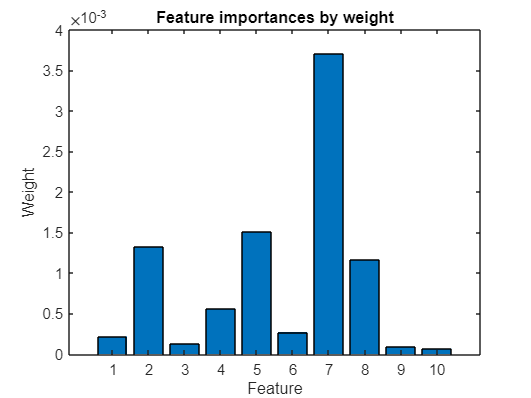


% plot feature importances by 'weight'
bar(fi);
title('Feature importances by weight');
xlabel('Feature');
ylabel('Weight');